## Plot acceleration readings for samples selection for recording 1

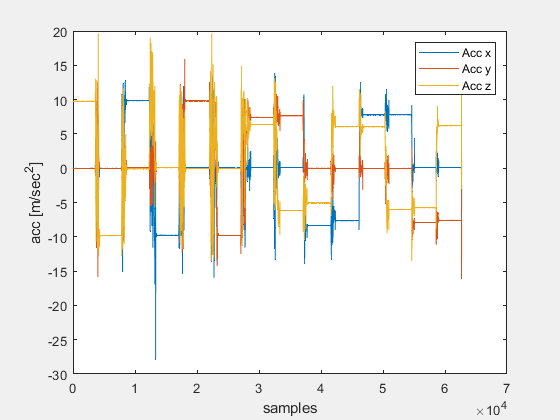

load('rec_1_all_faces_and_edges.mat')
h = figure(1);
set(gcf,'Visible','on')
plot(Acceleration.X,'DisplayName','Acc x')
hold on
plot(Acceleration.Y,'DisplayName','Acc y')
plot(Acceleration.Z,'DisplayName','Acc z')
legend
xlabel('samples')
ylabel('acc [m/sec^2]')

## Pick static sections

sections = [];
counter = 1;
forever = 1;
while forever
    drawnow
    [x,~] = ginput(2);
    sections(counter,1:2) = [floor(x(1)) floor(x(2))];
    counter = counter + 1;
    pause(1)
    isKeyPressed = strcmp('a',get(h,'CurrentCharacter'));
    if isKeyPressed
        break
    end
end

Error using ginput
Interrupted by figure deletion

clear isKeyPressed x h
close all

## Calculate acceleration average values per static section

avg_acc_per_sector = zeros(30,3);
for section = 1:counter-1
    avg_acc_x = mean(Acceleration.X(sections(section,1):sections(section,2)));
    avg_acc_y = mean(Acceleration.Y(sections(section,1):sections(section,2)));
    avg_acc_z = mean(Acceleration.Z(sections(section,1):sections(section,2)));
    avg_acc_per_sector(section,1:3) = [avg_acc_x avg_acc_y avg_acc_z];
end
clear avg_acc_x avg_acc_y avg_acc_z

## Plot acceleration readings for samples selection for recording 2

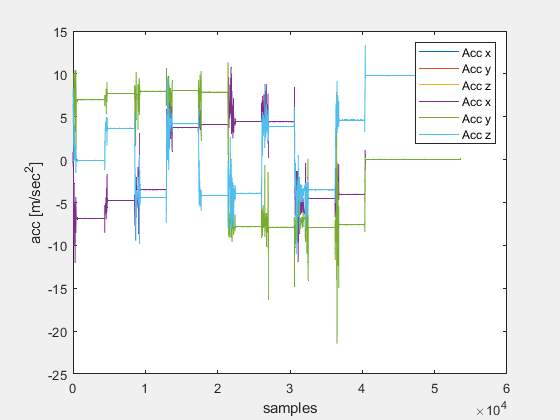

load('rec_2_All_corners_and_120sec_static.mat')
h = figure(1);
set(gcf,'Visible','on')
plot(Acceleration.X,'DisplayName','Acc x')
hold on
plot(Acceleration.Y,'DisplayName','Acc y')
plot(Acceleration.Z,'DisplayName','Acc z')
legend
xlabel('samples')
ylabel('acc [m/sec^2]')

## Pick static sections

counter_rec2 = 1;
forever = 1;
while forever
    drawnow
    [x,y] = ginput(2);
    sections(counter-1+counter_rec2,1:2) = [floor(x(1)) floor(x(2))];
    counter_rec2 = counter_rec2 + 1;
    pause(1)
    isKeyPressed = strcmp('a',get(h,'CurrentCharacter'));
    if isKeyPressed
        break
    end
end
clear x isKeyPressed forever h
close all

## Calculate acceleration average values per static section

for section = counter:counter+counter_rec2-2
    avg_acc_x = mean(Acceleration.X(sections(section,1):sections(section,2)));
    avg_acc_y = mean(Acceleration.Y(sections(section,1):sections(section,2)));
    avg_acc_z = mean(Acceleration.Z(sections(section,1):sections(section,2)));
    avg_acc_per_sector(section,1:3) = [avg_acc_x avg_acc_y avg_acc_z];
end
clear avg_acc_x avg_acc_y avg_acc_z
avg_acc_per_sector = avg_acc_per_sector(1:length(sections),:);

## Call optimization function

[M,B] = Acc_calib_opt(avg_acc_per_sector);

0001.869913e-0800000
0005.404921e-0400000
0001.093988e-1100000
Convergence achieved


M =     0.9994   -0.0001   -0.0002
   -0.0001    0.9998   -0.0001
   -0.0002   -0.0001    0.9983


B =     0.0041
    0.0004
   -0.0019
